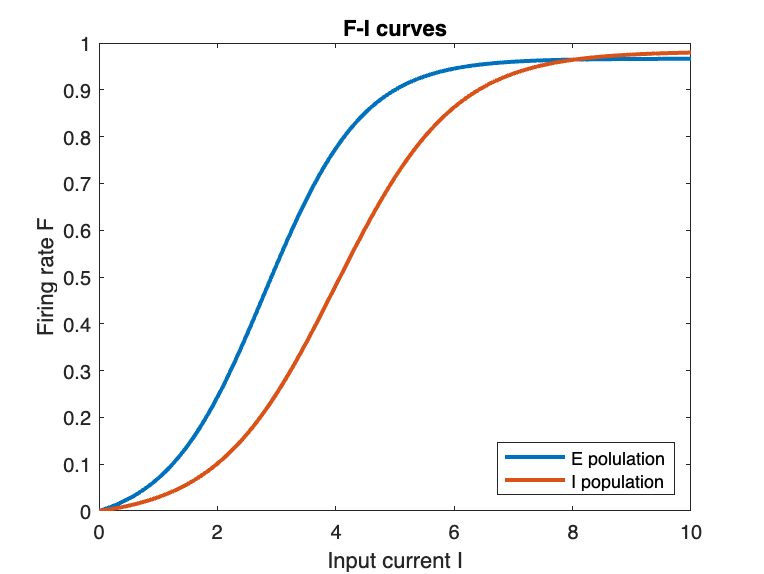

clear; clf;
numNeurons = 200;

%Simulation parameters
T = 50;
dt = 0.1;                       %Time step
range_t = 0:dt:T;               %Time axis
Li = length(range_t);
%rE_init= 0.22;
%rI_init= 0.73;
rE_init_rand = rand(numNeurons/2, 1); %We can define a random initial condition array
rI_init_rand = rand(numNeurons/2, 1); %Every neuron will start at random position

% Excitatory parameters
tau_E = 1;                      %Timescale of the E population [ms]
a_E = 1.2;                      %Gain of the E population
theta_E = 2.8;                  %Threshold of the E population
% Inhibitory parameters
tau_I = 2;                      %Timescale of the I population [ms]
a_I = 1;                        %Gain of the I population
theta_I = 4;                    %Threshold of the E population

% F-I curves of each population
x_gauss = 0:.1:10;
figure(1)
plot(x_gauss, F(x_gauss, a_E, theta_E), LineWidth=2)
hold on
plot(x_gauss, F(x_gauss, a_I, theta_I), LineWidth=2)
hold off
title('F-I curves')
xlabel('Input current I')
ylabel('Firing rate F')
legend('E polulation', 'I population', Location='southeast')

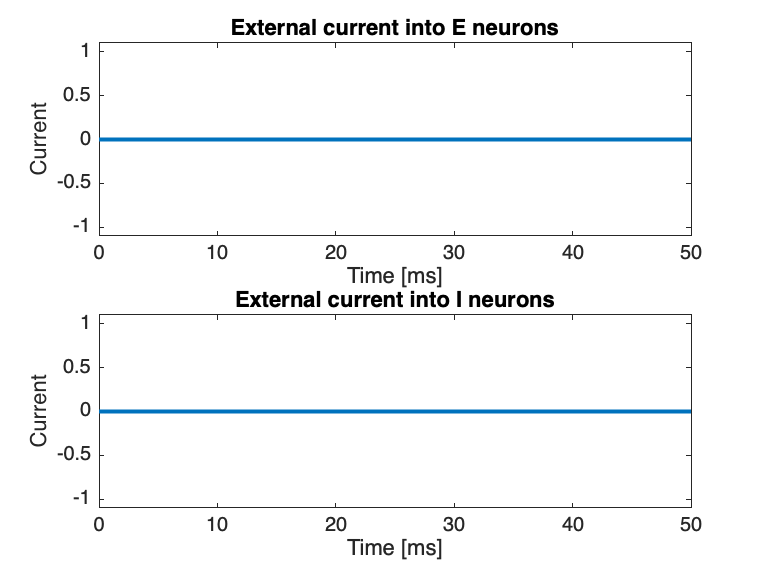


% External input
I_ext_E = 0*squarePulse(200, 300, zeros(1, Li));
I_ext_I = zeros(1, Li);

% Plot input currents
figure(2)
subplot(2, 1, 1)
plot(range_t, I_ext_E,'LineWidth', 2)
xlabel('Time [ms]')
ylabel('Current')
ylim([-1.1 1.1])
title('External current into E neurons')
subplot(2, 1, 2)
plot(range_t, I_ext_I, 'LineWidth', 2)
xlabel('Time [ms]')
ylabel('Current')
ylim([-1.1 1.1])
title('External current into I neurons')

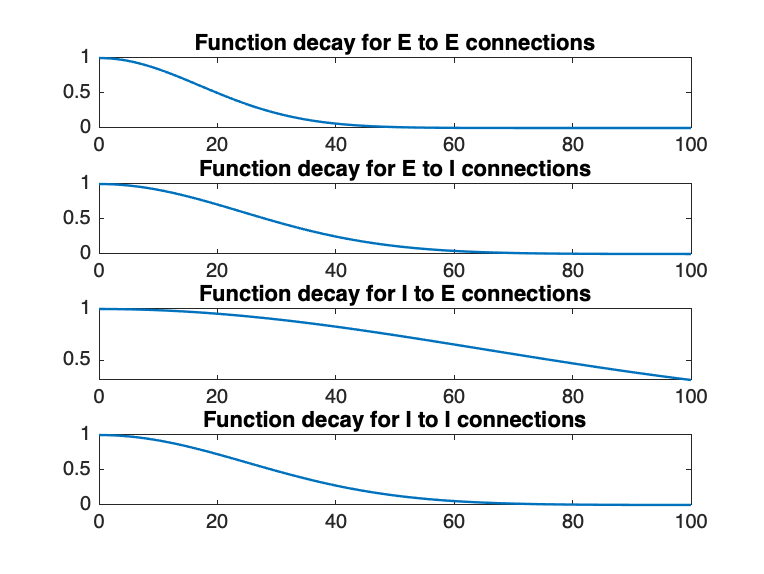


% Initialising the network 
space = zeros(1, numNeurons);   %The configuration of the system will stored in 
                                %this variable

%In this program there are only two types of neurons (E or I)
%In this network E and I neurons alternate each other

for i=1:numNeurons
    if rem(i,2) ~= 0            %Add a E neuron if the number is odd
        space(1, i) = 1;        %1 will indicate a excitatory neuron,
                                %0 indicates an inhibirotry one
    end                         
end

% Gaussian distance-related decay
x_gauss = 0:1:numNeurons/2;                  %Range for the Gaussian distribution
                                %Last term should be not less than dmax
sigma_ee = 17;
sigma_ie = 24;
sigma_ei = 65;
sigma_ii = 25;

% Plot connection strength decay
figure(3)
Gee = normGauss(x_gauss, sigma_ee);
subplot(4,1,1)
plot(x_gauss, Gee, 'LineWidth',   1.2)
title('Function decay for E to E connections')

Gie = normGauss(x_gauss, sigma_ie);
subplot(4,1,2)
plot(x_gauss, Gie, 'LineWidth',   1.2)
title('Function decay for E to I connections')

Gei = normGauss(x_gauss, sigma_ei);
subplot(4,1,3)
plot(x_gauss, Gei, 'LineWidth',   1.2)
title('Function decay for I to E connections')

Gii = normGauss(x_gauss, sigma_ii);
subplot(4,1,4)
plot(x_gauss, Gii, 'LineWidth',   1.2)
title('Function decay for I to I connections')

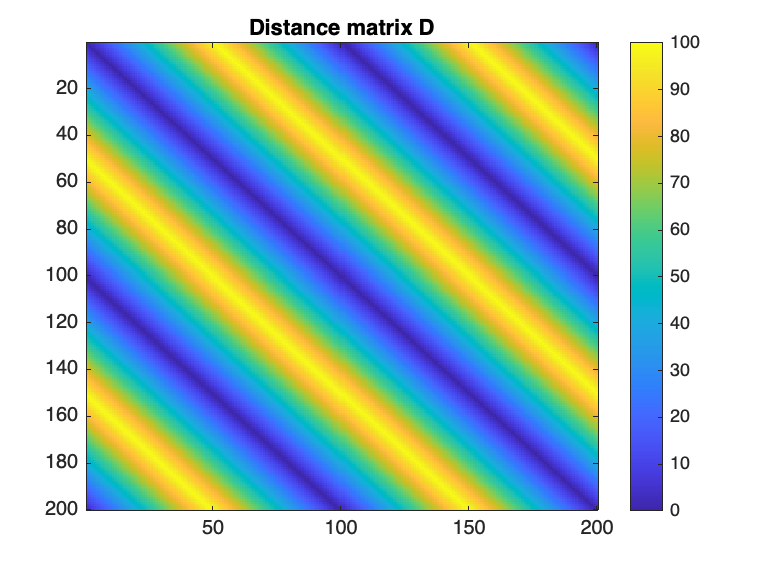



Dee = Dmatrix(numNeurons, 1, 1, space);
Die = Dmatrix(numNeurons, 1, 2, space);
Dei = Dmatrix(numNeurons, 2, 1, space);
Dii = Dmatrix(numNeurons, 2, 2, space);

D = [Dee Dei; Die Dii];
figure(4)
imagesc(D)
colorbar
title('Distance matrix D')

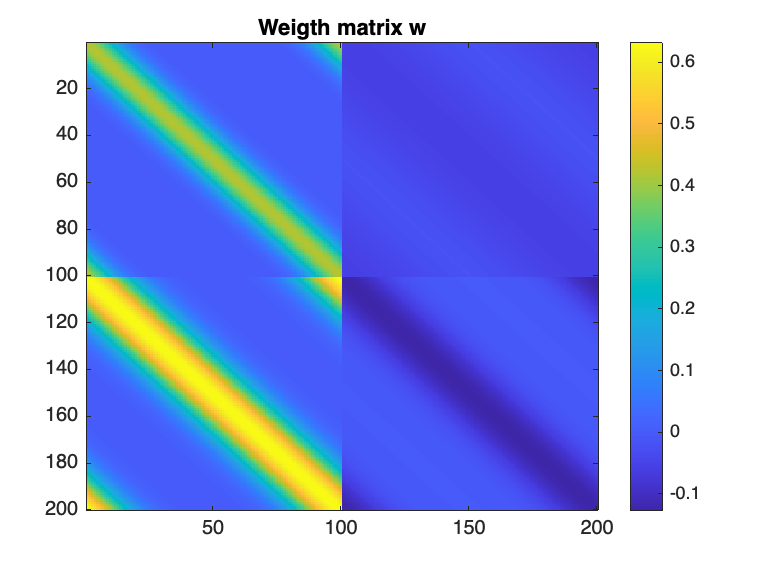


Wee = Wmatrix(numNeurons, Dee, Gee);
Wie = Wmatrix(numNeurons, Die, Gie);
Wei = Wmatrix(numNeurons, Dei, Gei);
Wii = Wmatrix(numNeurons, Dii, Gii);

% Normalisation by the total weight a post-synaptic neuron receives
Aee = 9;
Aei = 4;
Aie = 19;
Aii = 4;
A = [Aee -Aei; Aie -Aii];

See = sum(Wee, 2);
Mee = sum(See, 1)/length(See);
Wee = Aee*Wee/Mee;

Sei = sum(Wei, 2);
Mei = sum(Sei, 1)/length(Sei);
Wei = Aei*Wei/Mei;

Sie = sum(Wie, 2);
Mie = sum(Sie, 1)/length(Sie);
Wie = Aie*Wie/Mie;

Sii = sum(Wii, 2);
Mii = sum(Sii, 1)/length(Sii);
Wii = Aii*Wii/Mii;


We = [Wee -Wei];
Wi = [Wie -Wii];
W = [We; Wi];





figure(5)
imagesc(W)
colorbar
title('Weigth matrix w')

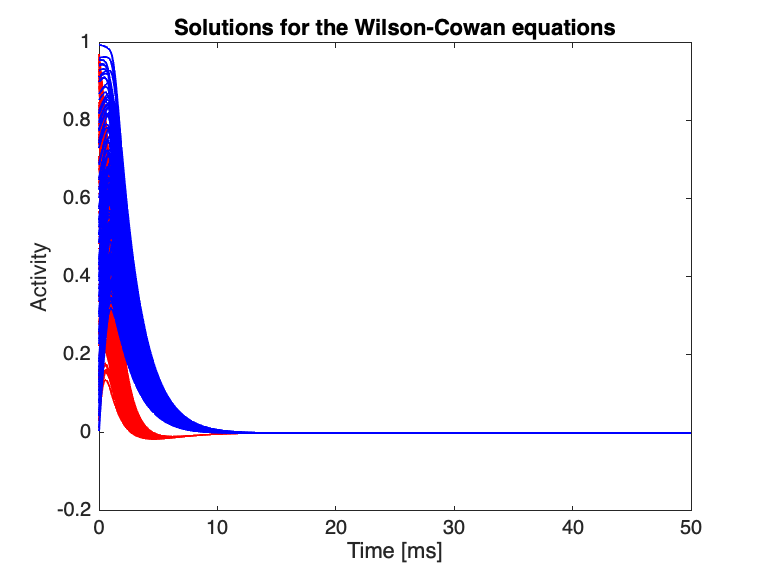

%Initialise rE matrix for all the E neurons

rE = zeros(numNeurons/2, Li);
rE(:,1) = rE_init_rand;              %In this simulation all the E neurons
                                %start at rE(0) = rE_init

%Initialise rI matrix for all the I neurons
rI = zeros(numNeurons/2, Li);
rI(:,1) = rI_init_rand;              %In this simulation all the E neurons
                                %start at rE(0) = rE_init


%Simulate the Wilson-Cowan equations



r = [rE; rI];

for i=1:Li-1
    drE = dt/tau_E*(-rE(:,i)+F(We*r(:,i)+I_ext_E(i), a_E, theta_E));
    drI = dt/tau_I*(-rI(:,i)+F(Wi*r(:,i)+I_ext_I(i), a_I, theta_I));
    dr = [drE; drI];

    rE(:, i+1) = rE(:, i) + drE;
    rI(:, i+1) = rI(:, i) + drI;
    rE(:, i+1) = rE(:, i) + drE;
    r(:, i+1) = r(:, i) + dr;
end

%Plot Wilson-Cowan results
figure(6)
plot(range_t, rE, 'LineWidth', 1.2, 'Color', 'red' )
hold on
plot(range_t, rI, 'LineWidth', 1.2, 'Color', 'blue')
ylabel('Activity')
xlabel('Time [ms]')
title('Solutions for the Wilson-Cowan equations')
hold off

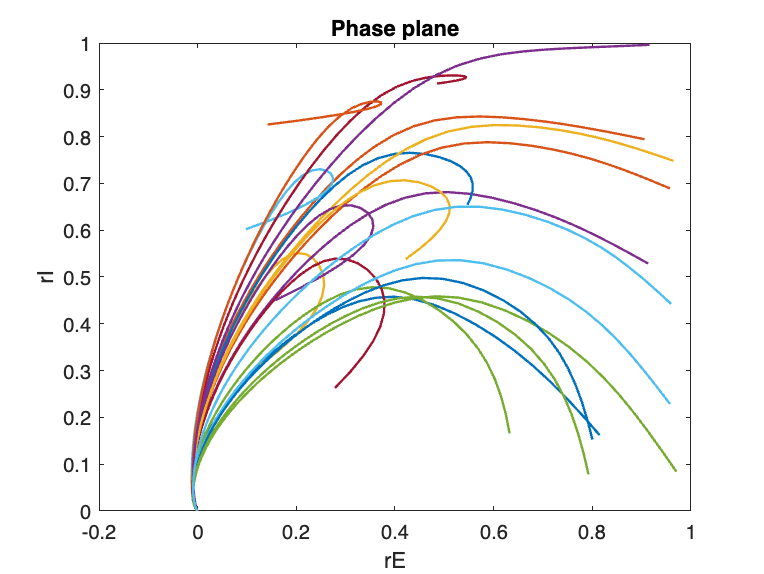


%Phase plane analysis
figure(7)
for i=1:20
    plot(rE(i, :), rI(i, :), 'LineWidth', 1.2)
    hold on
end
hold off
xlabel('rE')
ylabel('rI')
title('Phase plane')

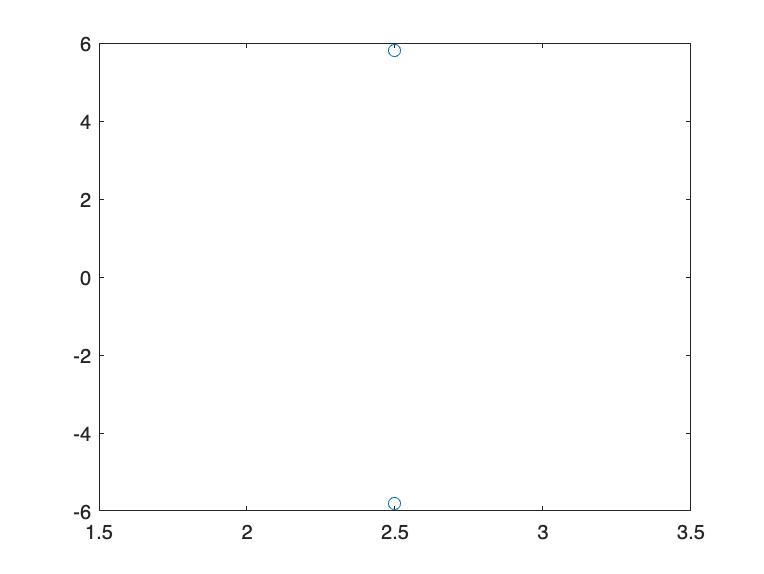


e = eig(A);
plot(real(e), imag(e), 'o');

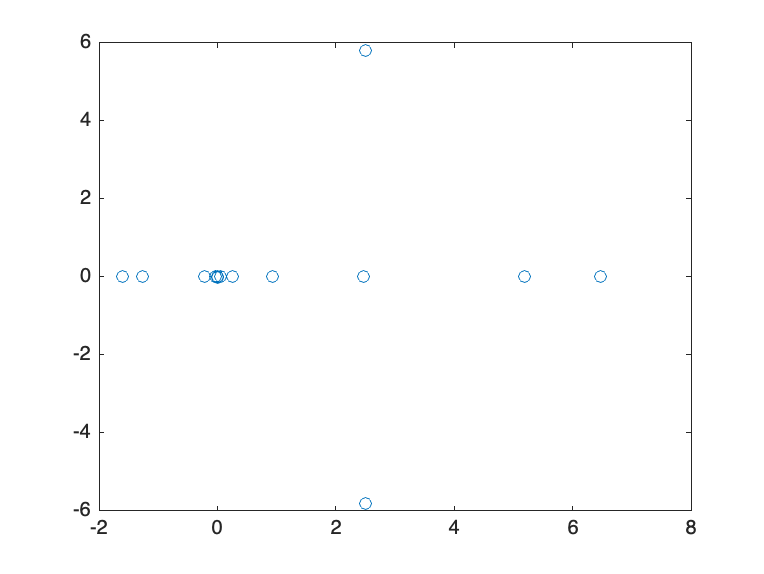


e = eig(W);
plot(real(e), imag(e), 'o')

function f = F(x, a, theta)
    f = (1 + exp(-a * (x - theta))).^-1 - (1 + exp(a * theta)).^-1;
end

function d = nDistance(n1, n2, v) %This function computes the distamce between two neurons
                                  %placed in a circular vector
    l = length(v);
    dmax= l/2;
    
    if n1 <= dmax && n2 <= n1 + dmax
        d = abs(n2 - n1);
    
    elseif n1 <= dmax && n2 > n1 + dmax
        d = l-n2+n1;
    
    
    elseif n1 > dmax && n2 > n1 && n2 <= l
        d = n2 - n1;
    
    
    elseif n1 > dmax && n2 <= n1 - dmax
        d = (l-n1) + n2;
    
    
    elseif n1 > dmax && n2 > n1 - dmax
        d = n1 - n2;
    end

end

function D = Dmatrix(numNeurons,n1, n2, space)
    M = zeros(numNeurons/2, numNeurons/2);
    
    r = 1;
    for j=n2:2:numNeurons
        c = 1;
        for i=n1:2:numNeurons
            M(c,r) = nDistance(j,i, space);
            c = c+1;
        end
        r = r+1;
    end
    D = M;
end

function W = Wmatrix(numNeurons, D, F)
    M = zeros(numNeurons/2, numNeurons/2);
    for j=1:numNeurons/2
        for i=1:numNeurons/2
            M(j,i) = F(D(j,i)+1);
        end
    end
    W = M; 
end

function G = normGauss(x, sigma)
    gauss = normpdf(x,0,sigma);
    G = gauss/max(gauss);  %Normalising the Gaussian distribution
end

function f = squarePulse(n1, n2, I)
    for i=n1:n2 
        I(i)=1;
    end
    f = I;
end

